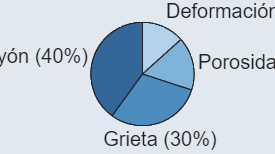

categorias = {'Rayón', 'Grieta', 'Porosidad', 'Deformación'};
frecuencias = [24, 18, 10, 8];
porcentajes = round(frecuencias / sum(frecuencias) * 100, 1);

etiquetas = strcat(categorias, {' ('}, string(porcentajes), {'%)'});

color_fondo = [226 232 240] / 255;

figure('Color', color_fondo);
set(gcf, 'Units', 'inches', 'Position', [0 0 5 2.8]);

p = pie(frecuencias, etiquetas);
colormap([0.2 0.4 0.6; 0.3 0.55 0.75; 0.5 0.7 0.85; 0.7 0.82 0.92]);

for i = 2:2:length(p)
    p(i).FontSize = 12;
end

exportgraphics(gcf, 'torta_tipo_falla.png', 'Resolution', 300);